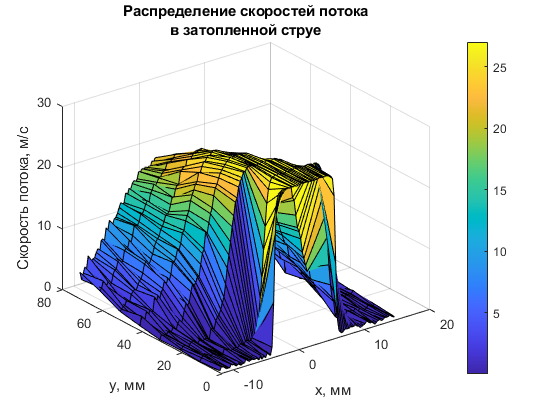


mm01 = load('01mm.dat');
mm11 = load('11mm.dat');
mm21 = load('21mm.dat');
mm31 = load('31mm.dat');
mm41 = load('41mm.dat');
mm51 = load('51mm.dat');
mm61 = load('61mm.dat');
mm71 = load('71mm.dat');

dx = 0.25; 
x = mm01(:, 1)' * 0.25;

p01 = polyval(c, mm01(:, 2));
p11 = polyval(c, mm11(:, 2));
p21 = polyval(c, mm21(:, 2));
p31 = polyval(c, mm31(:, 2));
p41 = polyval(c, mm41(:, 2));
p51 = polyval(c, mm51(:, 2));
p61 = polyval(c, mm61(:, 2));
p71 = polyval(c, mm71(:, 2));

pressure = [p01, p11, p21, p31, p41, p51, p61, p71];
xCentered = zeros(size(pressure));
sp = zeros(size(pressure));
offset = 50;
%hold on;

z = [1, 11, 21, 31, 41, 51, 61, 71];

for i = 1 : size(pressure, 2)
    sp(:, i) = sqrt(abs(2 * pressure(:, i) / 1.2));
    
    right = x(find(pressure(:, i) > offset, 1, 'last'));
    left = x(find(pressure(:, i) > offset, 1));
 
    center = left + (right - left) / 2;
    xCentered(:, i) = x - center;
    [X, Y] = meshgrid(xCentered(:, i), z);
    Z = sp';
    surf(X,Y,Z);
    colorbar;
    
    title({'Распределение скоростей потока', 'в затопленной струе'});
    xlabel('x, мм');
    ylabel('y, мм');
    zlabel('Скорость потока, м/с')
end